clear; clc; close all
rng(42);

% Immagini
path = fullfile('Dataset', 'Da usare');
imgs = imageDatastore(path, "IncludeSubfolders", true, "LabelSource", "foldernames");

# Split dataset

% 70 - 15 - 15
[imgsTrain, imgsTemp] = splitEachLabel(imgs, 0.7, "randomized");
[imgsVal, ~] = splitEachLabel(imgsTemp, 0.5, "randomized");

%Valutare augmentation

# Architettura

layers = [
    imageInputLayer([224 224 1], ...
    "Normalization","zerocenter")

    convolution2dLayer(3, 8, "Padding","same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, "Stride",2)

    convolution2dLayer(3, 16, "Padding","same")
    batchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, "Stride",2)

    dropoutLayer(0.2)

    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

# Addestramento

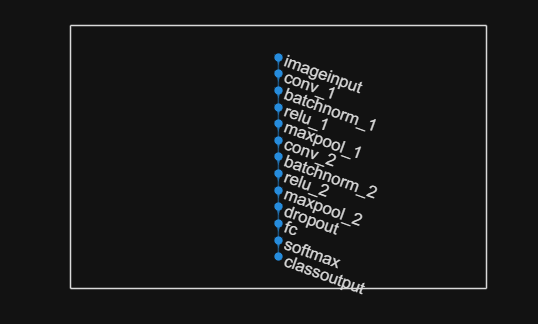

options = trainingOptions("adam", ...
    "ExecutionEnvironment","cpu", ...
    "DispatchInBackground", true, ...
    "ValidationPatience", 3, ...
    "InitialLearnRate", 1e-4, ...
    "MaxEpochs", 30, ...
    "MiniBatchSize", 32, ...

Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 4 workers.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:54 |       10.94% |        9.65% |       2.9485 |       3.3557 |      1.0000e-04 |
|       1 |          50 |       00:02:55 |       22.66% |              |       2.3224 |              |      1.0000e-04 |
|       1 |         100 |       00:04:56 |       35.16% |              |       1.7743 |              |      1.0000e-04 |
|   

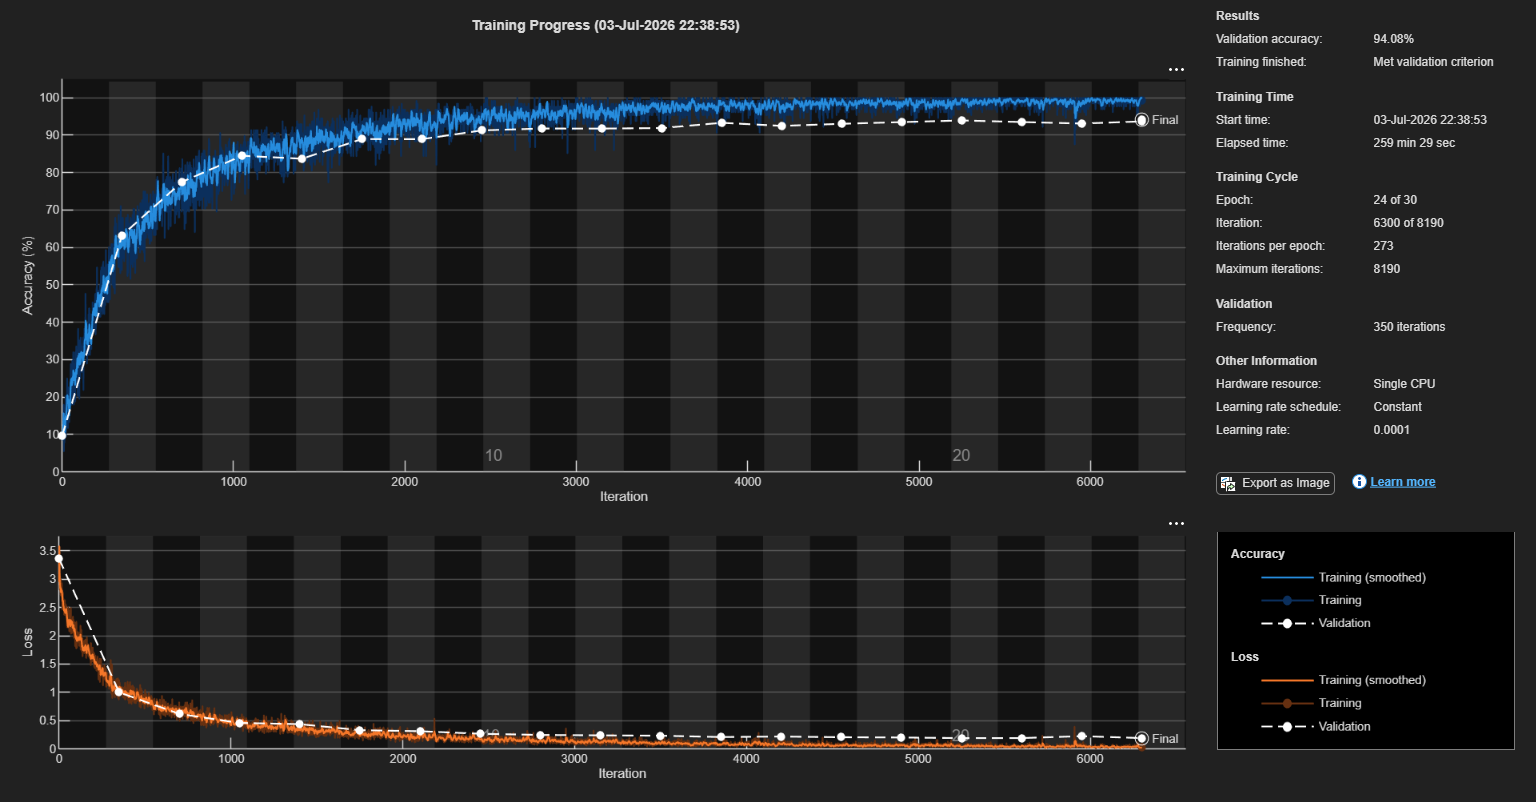

Error using save
Variable "layers" not found.

    "Shuffle", "every-epoch", ...
    "Plots", "training-progress", ...
    "ValidationData", imgsVal, ...
    "ValidationFrequency", floor(numObservations(trainingData)/MiniBatchSize), ...
    "Verbose",true);

net = trainNetwork(imgsTrain, layers, options);

save('rete.mat', 'net', 'options', 'layers')